% demos for HMM in ch13
d = 3; k = 2; n = 10000;
[x,model] = hmmRnd(d,k,n);

## Viterbi algorithm

[z, llh] = hmmViterbi(model, x);

## HMM filter (forward algorithm)

[alpha, llh] = hmmFilter(model, x);

## HMM smoother (forward backward)

[gamma,alpha,beta,c] = hmmSmoother(model, x);

## Baum-Welch algorithm

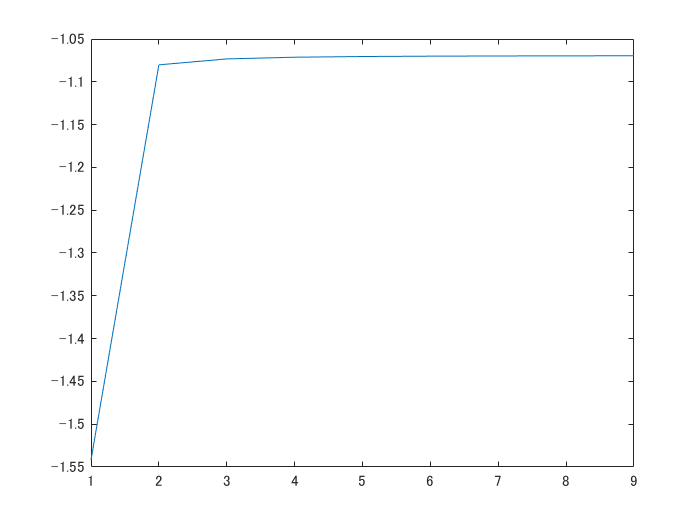

[model, llh] = hmmEm(x,k);
plot(llh)